# F2021 Opgave 4 - Regressionsmodel

clc; clear; close all; 

## Indlæsning af data

M = xlsread('Data_M4STI1_2021F.xlsx','G:I') 

M =     1.0000  110.0000  166.6000
    1.0000  150.0000  148.2000
    1.0000  190.0000  110.2000
    1.0000  230.0000   84.2000
    2.0000  110.0000  153.8000
    2.0000  150.0000  178.2000
    2.0000  190.0000   93.7000
    2.0000  230.0000  133.5000
    3.0000  110.0000  178.8000
    3.0000  150.0000  152.6000


x1 = M(:,1)

x1 =      1
     1
     1
     1
     2
     2
     2
     2
     3
     3


x2 = M(:,2)

x2 =    110
   150
   190
   230
   110
   150
   190
   230
   110
   150


y  = M(:,3)

y =   166.6000
  148.2000
  110.2000
   84.2000
  153.8000
  178.2000
   93.7000
  133.5000
  178.8000
  152.6000


n = size(y,1)   % Antal observationer: n = 20

n = 20

## a: Scatter plots

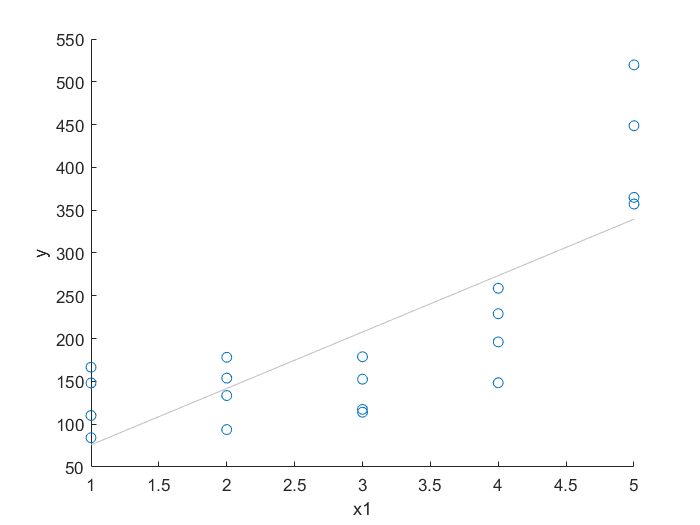

figure(1)
scatter(x1, y)
lsline
xlabel('x1')
ylabel('y')

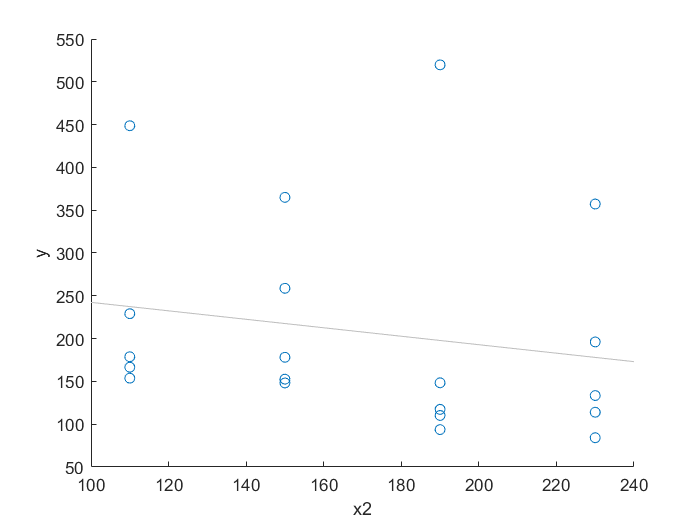


figure(2)
scatter(x2, y)
lsline
xlabel('x2')
ylabel('y')

Der er positiv korellation mellem x1 og y, og den ser lineær ud, indtil vi når til observationerne med x1 = 5.0. Sammenhængen kunne godt være eksponentiel. 

Der er negativ korellation mellem x2 og y, men den er rimeligt svag. De 5 observationer for hver værdi af x2 har meget variation, selvfølgelig pga. effekten af x1. 

## b: Multipel lineær regression

mdl1 = fitlm([x1, x2], y)

mdl1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)     94.094      76.163     1.2354       0.23347
    x1              65.905      12.058     5.4659    4.1848e-05
    x2             -0.4947     0.38129    -1.2974       0.21182


Number of observations: 20, Error degrees of freedom: 17
Root Mean Squared Error: 76.3
R-squared: 0.65,  Adjusted R-Squared: 0.609
F-statistic vs. constant model: 15.8, p-value = 0.000134

Regressionen giver dette funktionsudtryk:

y = 94.094 + 65.905*x1 - 0.4947*x2

## c: Beskriver modellen observationerne godt?

Det er ikke en god model. R-squared = 0.65 betyder, at kun 65 % af variationen i data er forklaret af modellen. Adjusted R-Squared = 0.609 er lidt lavere, så vi straffes lidt for at bruge både x1 og x2 i modellen. 

Det er kun koefficienten for x1 (b1 = 65.905), der er signifikant, med en pValue på 4.18e-05. P-værdien for intercept og x2 er begge langt over 0.05, nemlig hhv. 0.23 og 0.21. De to koefficinter b0 og b2 kan således sagtens være 0 i virkeligheden. 

F-værdien på 15.8 og den tilhørende p-værdi på 0.000134 viser, at mindst en af regressorvariablene har effekt på y.

## d: Interaktion

mdl2 = fitlm([x1, x2], y, 'y ~ x1 + x2 + x1:x2')

mdl2 = Linear regression model:
    y ~ 1 + x1*x2

Estimated Coefficients:
                   Estimate      SE        tStat      pValue 
                   ________    _______    ________    _______

    (Intercept)      128.14     161.73     0.79227    0.43979
    x1               54.558     48.764      1.1188    0.27974
    x2             -0.69495    0.92007    -0.75532    0.46103
    x1:x2           0.06675    0.27741     0.24062    0.81291


Number of observations: 20, Error degrees of freedom: 16
Root Mean Squared Error: 78.5
R-squared: 0.651,  Adjusted R-Squared: 0.586
F-statistic vs. constant model: 9.96, p-value = 0.000608

Det hjælper ikke at inddrage interaktion mellem x1 og x2. R-squared er næsten uændret, så vi forklarer kun ubetydeligt mere variation. Adjusted R-Squared reduceres (vi overfitter), og ingen af de fire koefficienter er nu  signifikant forskellige fra nul, da alle deres p-værdier er langt over 0.05. F-teststørrelsen på F=9.96 og den tilhørende p-værdi på 0.00608 viser dog stadig, at mindst en af regressorerne har effekt på y.

## e. Transformering

**Transformationsmodel 1**


$$y=b_0 +b_1 \mathrm{e}\mathrm{x}\mathrm{p}\left(x_1 \right)+b_2 x_2$$


expx1 = exp(x1)

expx1 =     2.7183
    2.7183
    2.7183
    2.7183
    7.3891
    7.3891
    7.3891
    7.3891
   20.0855
   20.0855


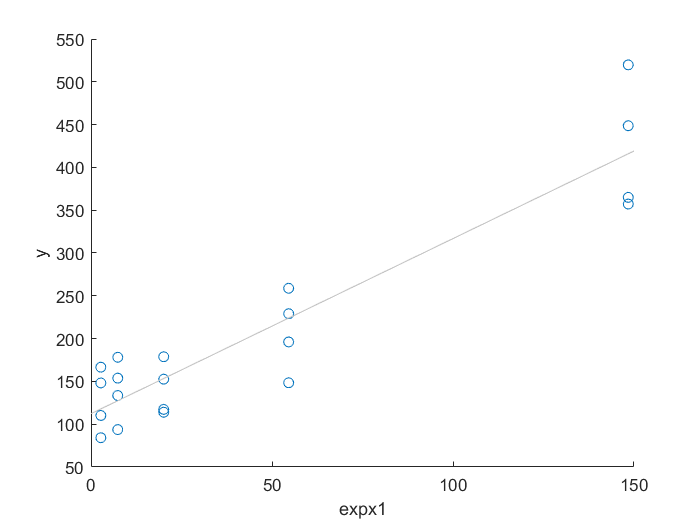


% Jeg tjekker lige korrelationen mellem exp(x1) og y:
figure(3)
scatter(expx1, y)
lsline
xlabel('expx1')
ylabel('y')

Det ser ganske godt ud. 

mdl3 = fitlm([expx1, x2], y)

mdl3 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      196.4      36.705     5.3507    5.2967e-05
    x1              2.0456     0.16881     12.118    8.6638e-10
    x2             -0.4947     0.20395    -2.4256      0.026704


Number of observations: 20, Error degrees of freedom: 17
Root Mean Squared Error: 40.8
R-squared: 0.9,  Adjusted R-Squared: 0.888
F-statistic vs. constant model: 76.4, p-value = 3.21e-09

**Transformationsmodel 2**


$$\mathrm{l}\mathrm{n}\left(y\right)=b_0 +b_1 x_1 +b_2 x_2$$


logy = log(y)

logy =     5.1156
    4.9986
    4.7023
    4.4332
    5.0357
    5.1829
    4.5401
    4.8941
    5.1863
    5.0278


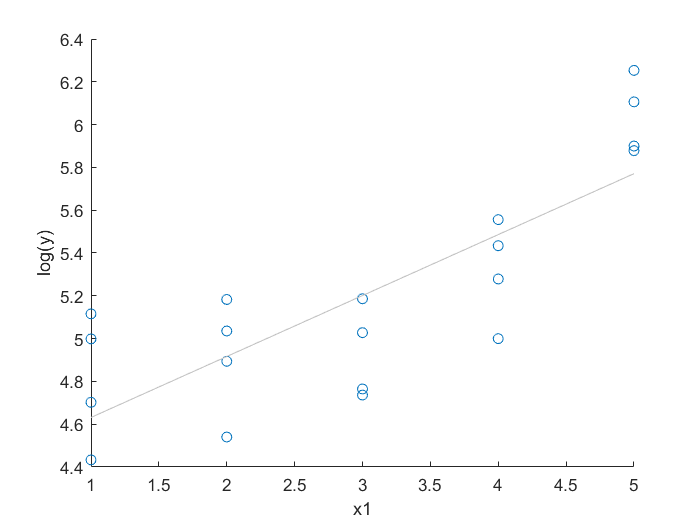


% Jeg tjekker også lige korrelationen mellem x1 og ln(y)
figure(4)
scatter(x1, logy)
lsline
xlabel('x1')
ylabel('log(y)')

Det ser ikke lineært ud.

mdl4 = fitlm([x1, x2], logy)

mdl4 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                    Estimate        SE         tStat       pValue  
                   __________    _________    _______    __________

    (Intercept)        4.8889      0.27952      17.49     2.645e-12
    x1                0.28482     0.044251     6.4364    6.1464e-06
    x2             -0.0031888    0.0013993    -2.2788      0.035872


Number of observations: 20, Error degrees of freedom: 17
Root Mean Squared Error: 0.28
R-squared: 0.733,  Adjusted R-Squared: 0.701
F-statistic vs. constant model: 23.3, p-value = 1.34e-05

**Sammenligning**

Begge modeller har signifikante koefficienter på 5 % signifikansniveau. Transformationsmodel 1 har markant højere værdi for R-Squared, nemlig 0.90 mod 0.73. Derfor er det en meget bedre model til at forklare data. Derfor vælger jeg transformeret model 1:

 y = 196.4 + 2.0456*exp(x1) - 0.4947*x2

##  f: Unormale punkter

Jeg laver analysen med den bedste model, mdl3.

lev = mdl3.Diagnostics.Leverage;        % hat diagonal
rst = mdl3.Residuals.Studentized;       % R-Student
nr = (1:n)';
resultat = [nr, x1, x2, y, lev, rst];   % Jeg samler det hele til et array
% Jeg laver array om til table, som bliver vist pænt med alle rækker:
resultat_tbl = array2table(resultat, ...
    'VariableNames',{'nr','x1','x2', 'y', 'lev', 'rst'})    

resultat_tbl = 20×6 table
    nr    x1    x2       y        lev          rst   
    __    __    ___    _____    ________    _________

     1    1     110    166.6     0.17304      0.50235
     2    1     150    148.2    0.093043      0.51483
     3    1     190    110.2    0.093043     0.055788
     4    1     230     84.2     0.17304     -0.10409
     5    2     110    153.8     0.16639    -0.085908
     6    2     150    178.2    0.086389       1.0521
     7    2     190     93.7    0.086389     -0.59936
     8    2     230    133.5     0.16639      0.95807
     9    3     110    178.8     0.15208     -0.11032
    10    3     150    152.6    0.072078     -0.26431
    11    3     190    117.3    0.072078     -0.65535
    12    3     230      114     0.15208     -0.25118
    13    4  

k = 2;                  % Der er to regressorer
lev_limit = 2*(k+1)/n   % lev_limit = 0.3

lev_limit = 0.3000

Observation nr. 17 og nr. 20 er begge løftestangspunkter, da lev = 0.3174,  som er over lev_limit = 0.3. 

Observation nr. 19 er en outlier, for |rst| = 4.9025, som er over grænsen på 3. 

Der er ingen indflydelsespunkter, for det kræver at samme punkt er både løftestangspunkt og outlier. 